clc;
clear all;

% Get the device information structure
info = audiodevinfo;

% Check if the 'input' field exists and has data
if isfield(info, 'input') && ~isempty(info.input)
    fprintf('Available Input Devices:\n');
    fprintf('---------------------------\n');

    % Loop through the input array directly
    for i = 1:length(info.input)
        fprintf('ID: %d | Name: %s\n', info.input(i).ID, info.input(i).Name);
    end
else
    disp('No input devices found.');
end

Available Input Devices:


---------------------------


ID: 0 | Name: Primary Sound Capture Driver (Windows DirectSound)
ID: 1 | Name: Microphone (USB PnP Audio Device) (Windows DirectSound)
ID: 2 | Name: Microphone Array (Realtek(R) Audio) (Windows DirectSound)



%% ── 0. PARAMETERS ────────────────────────────────────────
Fs            = 48000;   % Hz
nBits         = 16;
nChannels     = 1;
rec_duration  = 2;       % seconds
mic_spacing_m = 0.40;    % metres  ← SET YOUR ACTUAL SPACING
v_sound       = 343;     % m/s  (20 °C dry air)
bp_lo         = 85;      % bandpass low  Hz
bp_hi         = 300;    % bandpass high Hz  (widened for speech/click)
deviceID_1    = 1;       % Windows device index for mic 1
deviceID_2    = 2;       % Windows device index for mic 2

%% ── 1. RECORD ────────────────────────────────────────────
% --- Setup the Reader ---
% Note: If your USB mics are separate devices, you might need to
% aggregate them into a single 'Multi-device' or use a stereo interface.
deviceReader = audioDeviceReader(...
    'SampleRate', Fs, ...
    'NumChannels', 2, ... 
    'SamplesPerFrame', Fs * rec_duration); % Read the whole duration at once

setup(deviceReader);

fprintf('  ▶ RECORDING — Speak now!\n');

  ▶ RECORDING — Speak now!


% This reads both channels simultaneously
allData = deviceReader(); 

mic1 = allData(:,1);
mic2 = allData(:,2);

release(deviceReader);
fprintf('  ■ Done recording.\n');

  ■ Done recording.





%% ── 2. TRIM TO EQUAL LENGTH ──────────────────────────────
N   = min(length(mic1), length(mic2));
mic1 = mic1(1:N);
mic2 = mic2(1:N);
t   = (0:N-1).' / Fs;

% %% ── 3. CLOCK-DRIFT CORRECTION (USB jitter fix) ──────────
% %  Each USB mic has its own crystal; over 3 s the clocks can
% %  drift ~1–3 samples.  We use the initial sync click:
% %  find it in both signals, compute drift rate, resample mic2.
% fprintf('\n[STEP 3] Correcting USB clock drift...\n');
% 
% % Detect sync click = first large energy burst (top 1 % of abs)
% click_thresh = 0.5 * max(abs(mic1_raw));
% idx1_click   = find(abs(mic1_raw) > click_thresh, 1, 'first');
% idx2_click   = find(abs(mic2_raw) > click_thresh, 1, 'first');
% 
% if isempty(idx1_click) || isempty(idx2_click)
%     warning('Could not detect sync click — skipping drift correction.');
%     mic1 = mic1_raw;  mic2 = mic2_raw;
%     sync_offset = 0;
% else
%     sync_offset = idx1_click - idx2_click;   % samples mic2 is ahead/behind
%     drift_rate  = 1 + sync_offset / N;       % ratio
%     fprintf('  Sync click: mic1 sample %d, mic2 sample %d (offset %+d samples)\n', ...
%         idx1_click, idx2_click, sync_offset);
%     fprintf('  Drift rate: %.8f  →  resampling mic2\n', drift_rate);
% 
%     % Resample mic2 to compensate
%     [p, q]  = rat(drift_rate, 1e-6);
%     mic2_rc = resample(mic2_raw, p, q);
%     % Re-trim
%     N2      = min(length(mic1_raw), length(mic2_rc));
%     mic1    = mic1_raw(1:N2);
%     mic2    = mic2_rc(1:N2);
%     N       = N2;
%     t       = (0:N-1).' / Fs;
% end

% data = readmatrix('mic_data_40cm.csv');
% mic1 = data(:,1);
% mic2 = data(:,2);
% Fs = 40000; %Humans can hear up to about 20,000 Hz.
% nBits = 16;

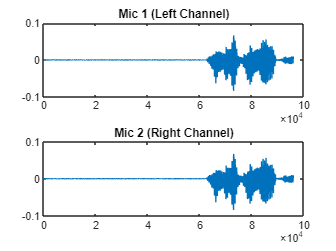

figure;
subplot(2,1,1); plot(mic1); title('Mic 1 (Left Channel)');
subplot(2,1,2); plot(mic2); title('Mic 2 (Right Channel)');

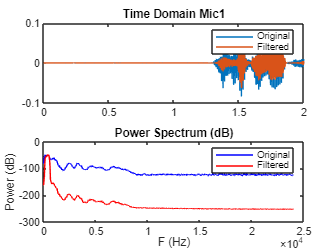

minLength = min(length(mic1), length(mic2));
mic1 = mic1(1:minLength);
mic2 = mic2(1:minLength);
t = (0:minLength-1) * (1/Fs);

% Lowpass
mic1_f = bandpass(mic1, [200 550], Fs);
mic2_f = bandpass(mic2, [200 550], Fs);

% Mic 1
figure; subplot(2,1,1);
plot(t, mic1); hold on; plot(t, mic1_f);
title('Time Domain Mic1'); legend('Original','Filtered');

subplot(2,1,2);
[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on; plot(ff1, 10*log10(pf1), 'r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');

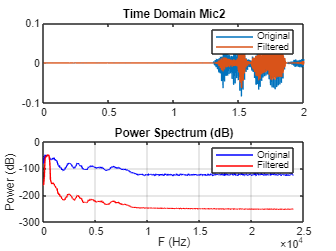


% Mic 2
figure; subplot(2,1,1);
plot(t, mic2); hold on; plot(t, mic2_f);
title('Time Domain Mic2'); legend('Original','Filtered');

subplot(2,1,2);
[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), '-b'); hold on; plot(ff2, 10*log10(pf2), '-r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');
grid on;

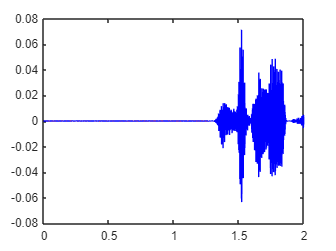


figure;
plot(t,mic1_f,"r")
hold on
plot(t,mic2_f,"b")
hold off

%sound(mic1_f,Fs)
sound(mic2_f,Fs)

% % --- Setup Parameters ---
% v = 343; 
% mic_spacing_m = 1.5;
% max_delay_s = mic_spacing_m / v;
% max_lag_samples = round(max_delay_s * Fs);
% 
% % --- GCC-PHAT Algorithm ---
% % 1. Transform to Frequency Domain
% N = length(mic1_f);
% X1 = fft(mic1_f);
% X2 = fft(mic2_f);
% 
% % 2. Calculate Cross-Power Spectrum
% G12 = X1 .* conj(X2);
% 
% % 3. Apply the PHAT Weighting (The "Whitening" step)
% % We divide by the magnitude to keep only the phase information
% W_phat = 1 ./ (abs(G12) + eps); % eps prevents division by zero
% gcc_phat_spectrum = G12 .* W_phat;
% 
% % 4. Transform back to Time Domain
% cc_raw = ifft(gcc_phat_spectrum);
% cc_shifted = fftshift(real(cc_raw)); % Center the zero-lag
% 
% % 5. Define the Lag Axis
% lags = (-floor(N/2) : floor(N/2)-1);
% 
% % --- Peak Detection within Physical Constraints ---
% % Limit search to max_lag_samples to ignore impossible distances
% valid_indices = find(abs(lags) <= max_lag_samples);
% [~, local_idx] = max(cc_shifted(valid_indices));
% idx = valid_indices(local_idx);
% 
% % --- Parabolic Interpolation for Sub-sample Accuracy ---
% if idx > 1 && idx < length(cc_shifted)
%     alpha = cc_shifted(idx - 1);
%     beta  = cc_shifted(idx);
%     gamma = cc_shifted(idx + 1);
% 
%     p = 0.5 * (alpha - gamma) / (alpha - 2*beta + gamma);
%     refined_lag = lags(idx) + p;
% else
%     refined_lag = lags(idx);
% end
% 
% % --- Final Calculation ---
% delay_final = refined_lag / Fs;
% distance_est = delay_final * v;
% 
% fprintf('GCC-PHAT Distance: %.4f m\n', distance_est);

% TDOA
mic_spacing_m = 1.5; % Set your actual mic spacing in meters
v_sound = 343;     % m/s
max_delay_s = mic_spacing_m / v_sound;   % e.g. ~0.003 s
max_lag_samples = round(max_delay_s * Fs) ;  
% Normalized cross-correlation (GCC-style, time domain)
[xc12, lags12] = xcorr(mic1_f, mic2_f, max_lag_samples, 'normalized');
[~, idx12] = max(abs(xc12));
lag12       = lags12(idx12);
delay12     = lag12 / Fs;

fprintf('Lag:   %d samples\n', lag12);

Lag:   0 samples


fprintf('Delay: %.6f s  (%.4f ms)\n', delay12, delay12*1000);

Delay: 0.000000 s  (0.0000 ms)



v = 343; 
distance_mic = delay12 * v;
fprintf('Distance: %.3f\n',distance_mic);

Distance: 0.000


L = 0.5;

% 1. Find the discrete peak as usual
[max_val, idx12] = max(xc12);

% 2. Ensure the peak isn't at the very edge of the cross-correlation array
if idx12 > 1 && idx12 < length(xc12)
    % Get the values of the peak and its neighbors
    alpha = xc12(idx12 - 1); % Value to the left
    beta  = xc12(idx12);     % The peak value
    gamma = xc12(idx12 + 1); % Value to the right

    % Formula for the fractional offset (p) from the center index
    % p is between -0.5 and 0.5
    p = 0.5 * (alpha - gamma) / (alpha - 2*beta + gamma);

    % 3. Calculate the refined lag
    refined_lag12 = lags12(idx12) + p;
else
    % Fallback if peak is at the boundary
    refined_lag12 = lags12(idx12);
end

% 4. Compute the refined delay and distance
delay12_refined = refined_lag12 / Fs;
distance_mic_refined = delay12_refined * v;

fprintf('Discrete Lag: %d samples\n', lags12(idx12));

Discrete Lag: 0 samples


fprintf('Refined Lag:  %.4f samples\n', refined_lag12);

Refined Lag:  -0.0003 samples


fprintf('Refined Dist: %.4f m\n', distance_mic_refined);

Refined Dist: -0.0000 m
